**Dataset Preparation**

# Normalize data

[no_load_both,full_load_both] = normalize_pressure()

no_load_both = 2.5589e+03

no_load_both = 	1.0e+03 *

    2.5589    2.1020


no_load_both = 	1.0e+03 *

    2.5589    2.1020    2.5311


no_load_both = 	1.0e+03 *

    2.5589    2.1020    2.5311    4.3931


no_load_both = 	1.0e+03 *

    2.5589    2.1020    2.5311    4.3931    2.8654


full_load_both = 3.7758e+03

full_load_both = 	1.0e+03 *

    3.7758    3.7333


full_load_both = 	1.0e+03 *

    3.7758    3.7333    4.1163


full_load_both = 	1.0e+03 *

    3.7758    3.7333    4.1163    7.6269


full_load_both = 	1.0e+03 *

    3.7758    3.7333    4.1163    7.6269    4.5042


no_load_both = 	1.0e+03 *

    2.5589    2.1020    2.5311    4.3931    2.8654


full_load_both = 	1.0e+03 *

    3.7758    3.7333    4.1163    7.6269    4.5042


# load Dataset

[data] = load_activity_data(no_load_both,full_load_both)

data = struct with fields:
    Inactive: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
       Stand: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
        Walk: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}
      Stairs: {{1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}  {1×2 cell}}


# calculate Features

window_size=2 % set windowsize in seconds

window_size = 2

[Features] = calculate_features(data, window_size)

Features = struct with fields:
                Max_Accel_Right_x: [1042×1 double]
                Max_Accel_Right_y: [1042×1 double]
                Max_Accel_Right_z: [1042×1 double]
                 Max_Accel_Left_x: [1042×1 double]
                 Max_Accel_Left_y: [1042×1 double]
                 Max_Accel_Left_z: [1042×1 double]
                Min_Accel_Right_x: [1042×1 double]
                Min_Accel_Right_y: [1042×1 double]
                Min_Accel_Right_z: [1042×1 double]
                 Min_Accel_Left_x: [1042×1 double]
                 Min_Accel_Left_y: [1042×1 double]
                 Min_Accel_Left_z: [1042×1 double]
                Std_Accel_Right_x: [1042×1 double]
                Std_Accel_Right_y: [1042×1 double]
                Std_Accel_Right_z: [1042×1 double]
                 Std_Accel_Left_x: [1042×1 double]
                 Std_Accel_Left_y: [1042×1 double]
                 Std_Accel_Left_z: [1042×1 double]
               Mean_Accel_Right_x: [1042×1 double]


# save Features in CSV

Features_table=struct2table(Features);
writetable(Features_table,'Features.csv');



# Plot Data in Scatter 2D Plots


colors=["cyan" "blue" "magenta" "black"]

colors = 1×6 string array
    "cyan"    "blue"    "magenta"    "black"    "yellow"    "green"


symbols=["*" "o" "x" "s" "d" "v"]

symbols = 1×6 string array
    "*"    "o"    "x"    "s"    "d"    "v"


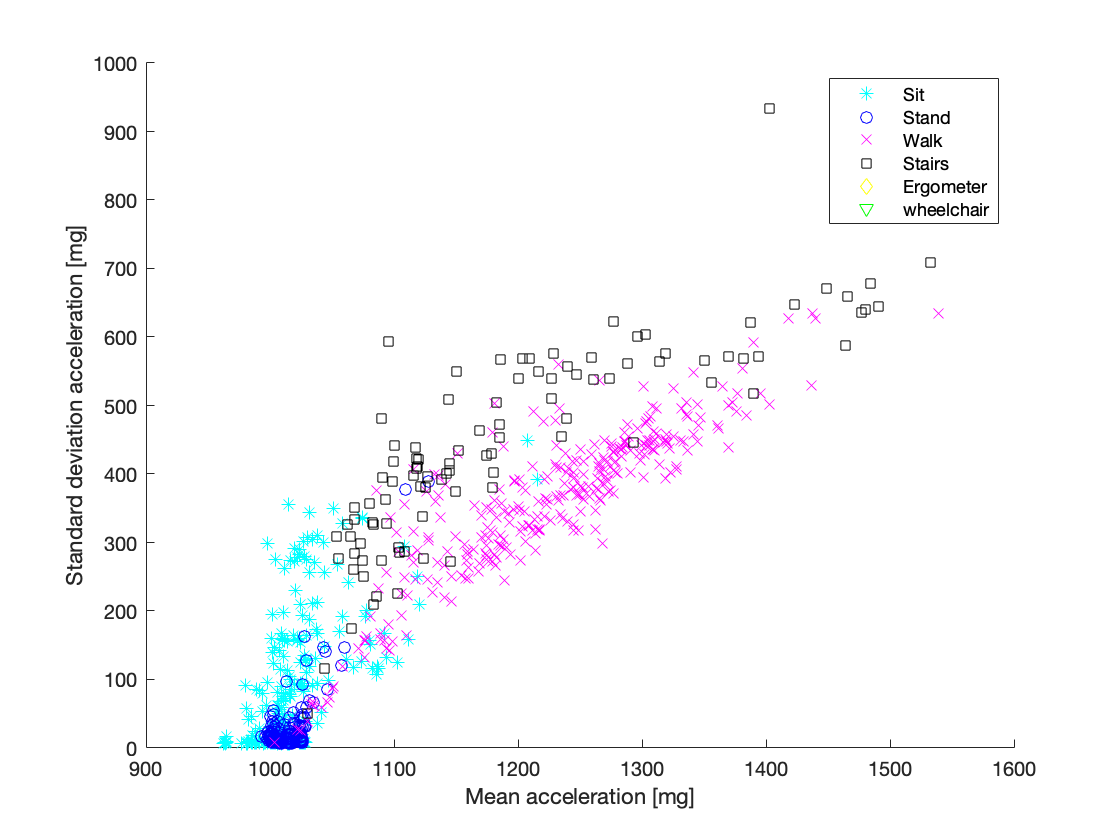


figure

hold on 
for i=1:length(colors)

scatter(Features.Mean_Mean_Accel_Left_right(Features.Class==i,1),Features.Mean_Std_Accel_Left_right(Features.Class==i,1),(symbols(i)),(colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs")

xlabel('Mean acceleration [mg]')   
ylabel('Standard deviation acceleration [mg]' )

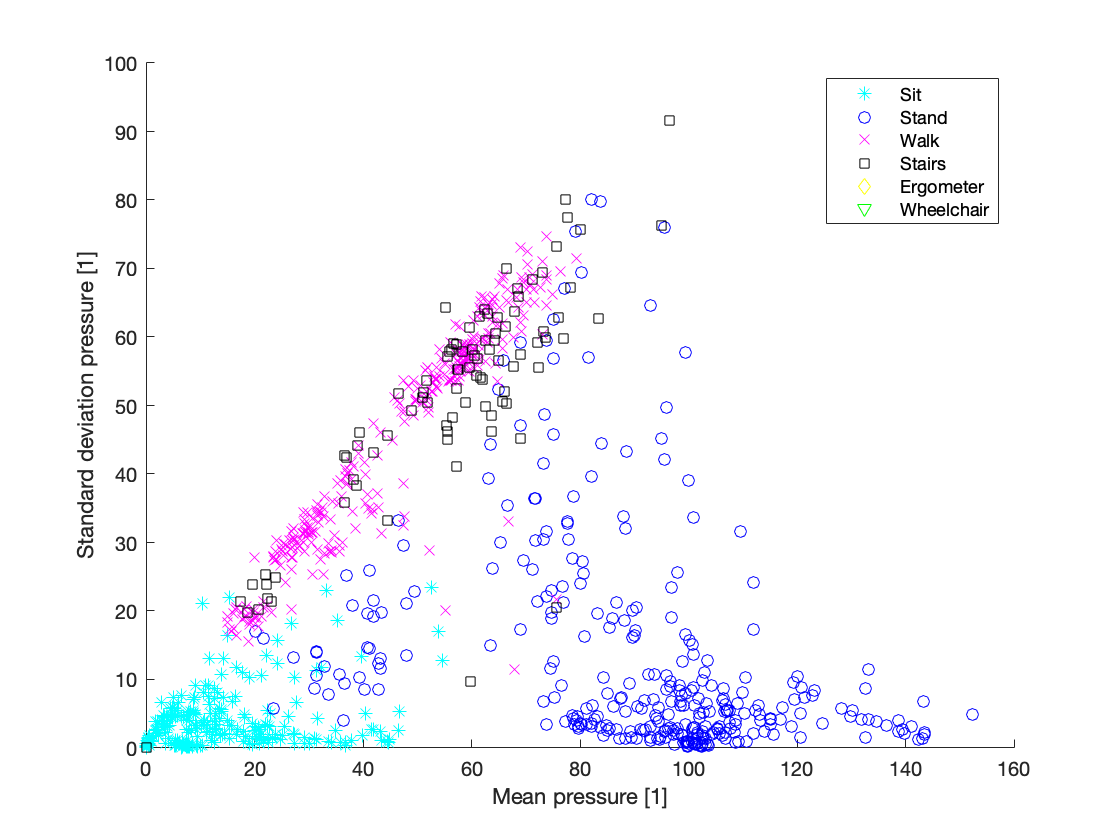

%set(gca, 'color', [0,0,1])



figure
for i=1:length(colors)

scatter(Features.Mean_Mean_Pressure_Left_right(Features.Class==i,1),Features.Mean_Std_Pressure_Left_right(Features.Class==i,1),(symbols(i)+colors(i)))
hold on 
end 

legend("Sit", "Stand", "Walk", "Stairs")

xlabel('Mean pressure [1]')   
ylabel('Standard deviation pressure [1]' )


clf

